% Load the steady-state inversion of the entire Greenland Ice Sheet
load('Greenland_Inversion_BedMechine.mat')

## Import the mass balance data for Transient simulation

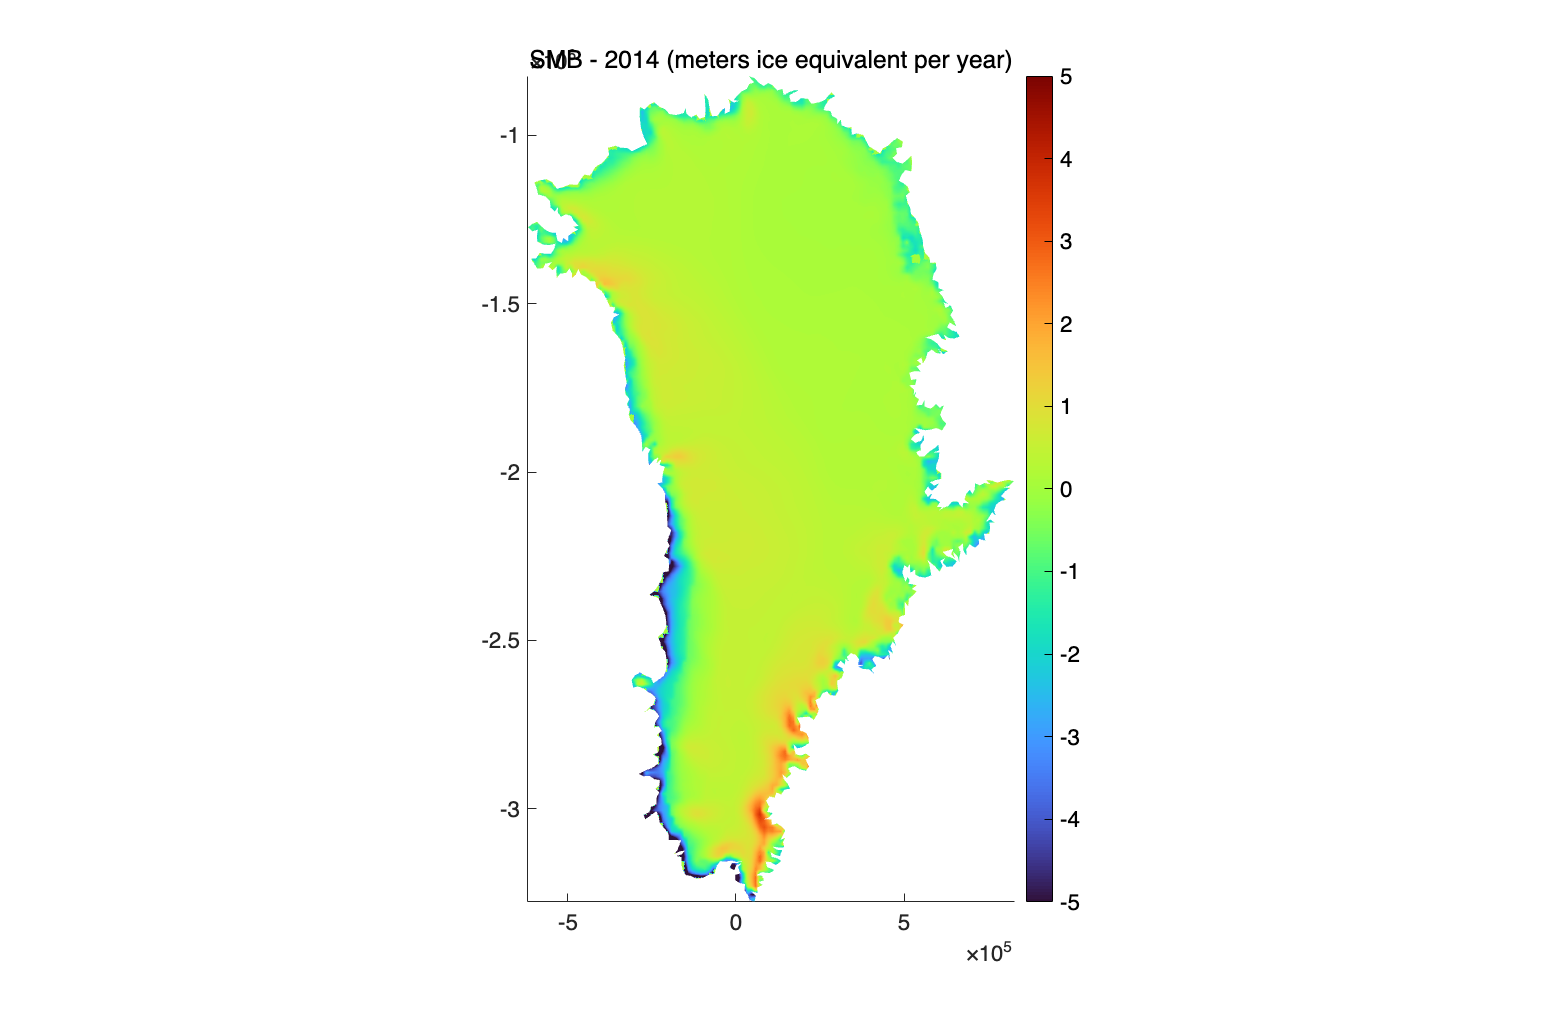

%------------------------------------------------------------------------
% Here I am using NASA GFSC Greenland surafce mass balance data for the
% ISSM model focing
%------------------------------------------------------------------------
% Read the SMB file and process the data (Coordinates and time)
filename = '/Users/rishi/Desktop/ISSM/examples/data/SMB_Greenland_NASA_GFSC.nc';
x = double(ncread(filename,'x')); % in meters
y = double(ncread(filename,'y')); % in meters
SMB = double(ncread(filename,'SMB')); % already in meters ice equivalent per year
SMB(SMB == -9999) = NaN; %replace missing values with nan
time = ncread(filename,'time');
dt = datetime(1980,1,1):days(5):datetime(2022,6,25); % same as the date matrix
years = unique(year(dt)); % get the years from the data

%  Force ISSM with the new SMB data 
% define your start and end years
initialtime = 2010;
finaltime   = 2022;

% find indices of years within the time window
selected_years = years(years >= initialtime & years <= finaltime);

% update the SMB forcing
md.smb.mass_balance = zeros(md.mesh.numberofvertices + 1, numel(selected_years));
md.smb.mass_balance(end, :) = selected_years;

for i = 1:numel(selected_years)
    % produce yearly average data from the 5-day average
    SMB_yearly(:,:,i) = mean(SMB(:,:,year(dt) == selected_years(i)), 3, 'omitnan');

    % force ISSM with the yearly surface mass balance observations
    md.smb.mass_balance(1:end-1, i) = ...
        InterpFromGridToMesh(x, y, SMB_yearly(:,:,i), md.mesh.x, md.mesh.y, 0);
end

% change the nan values to zero for the sake of model run
md.smb.mass_balance(isnan(md.smb.mass_balance)) = 0;

% plot the smb data for greenland
plotmodel(md,'data',md.smb.mass_balance(1:end-1,1),'title','SMB - 2014 (meters ice equivalent per year)','caxis',[-5 5])

## Plot the SMB time series

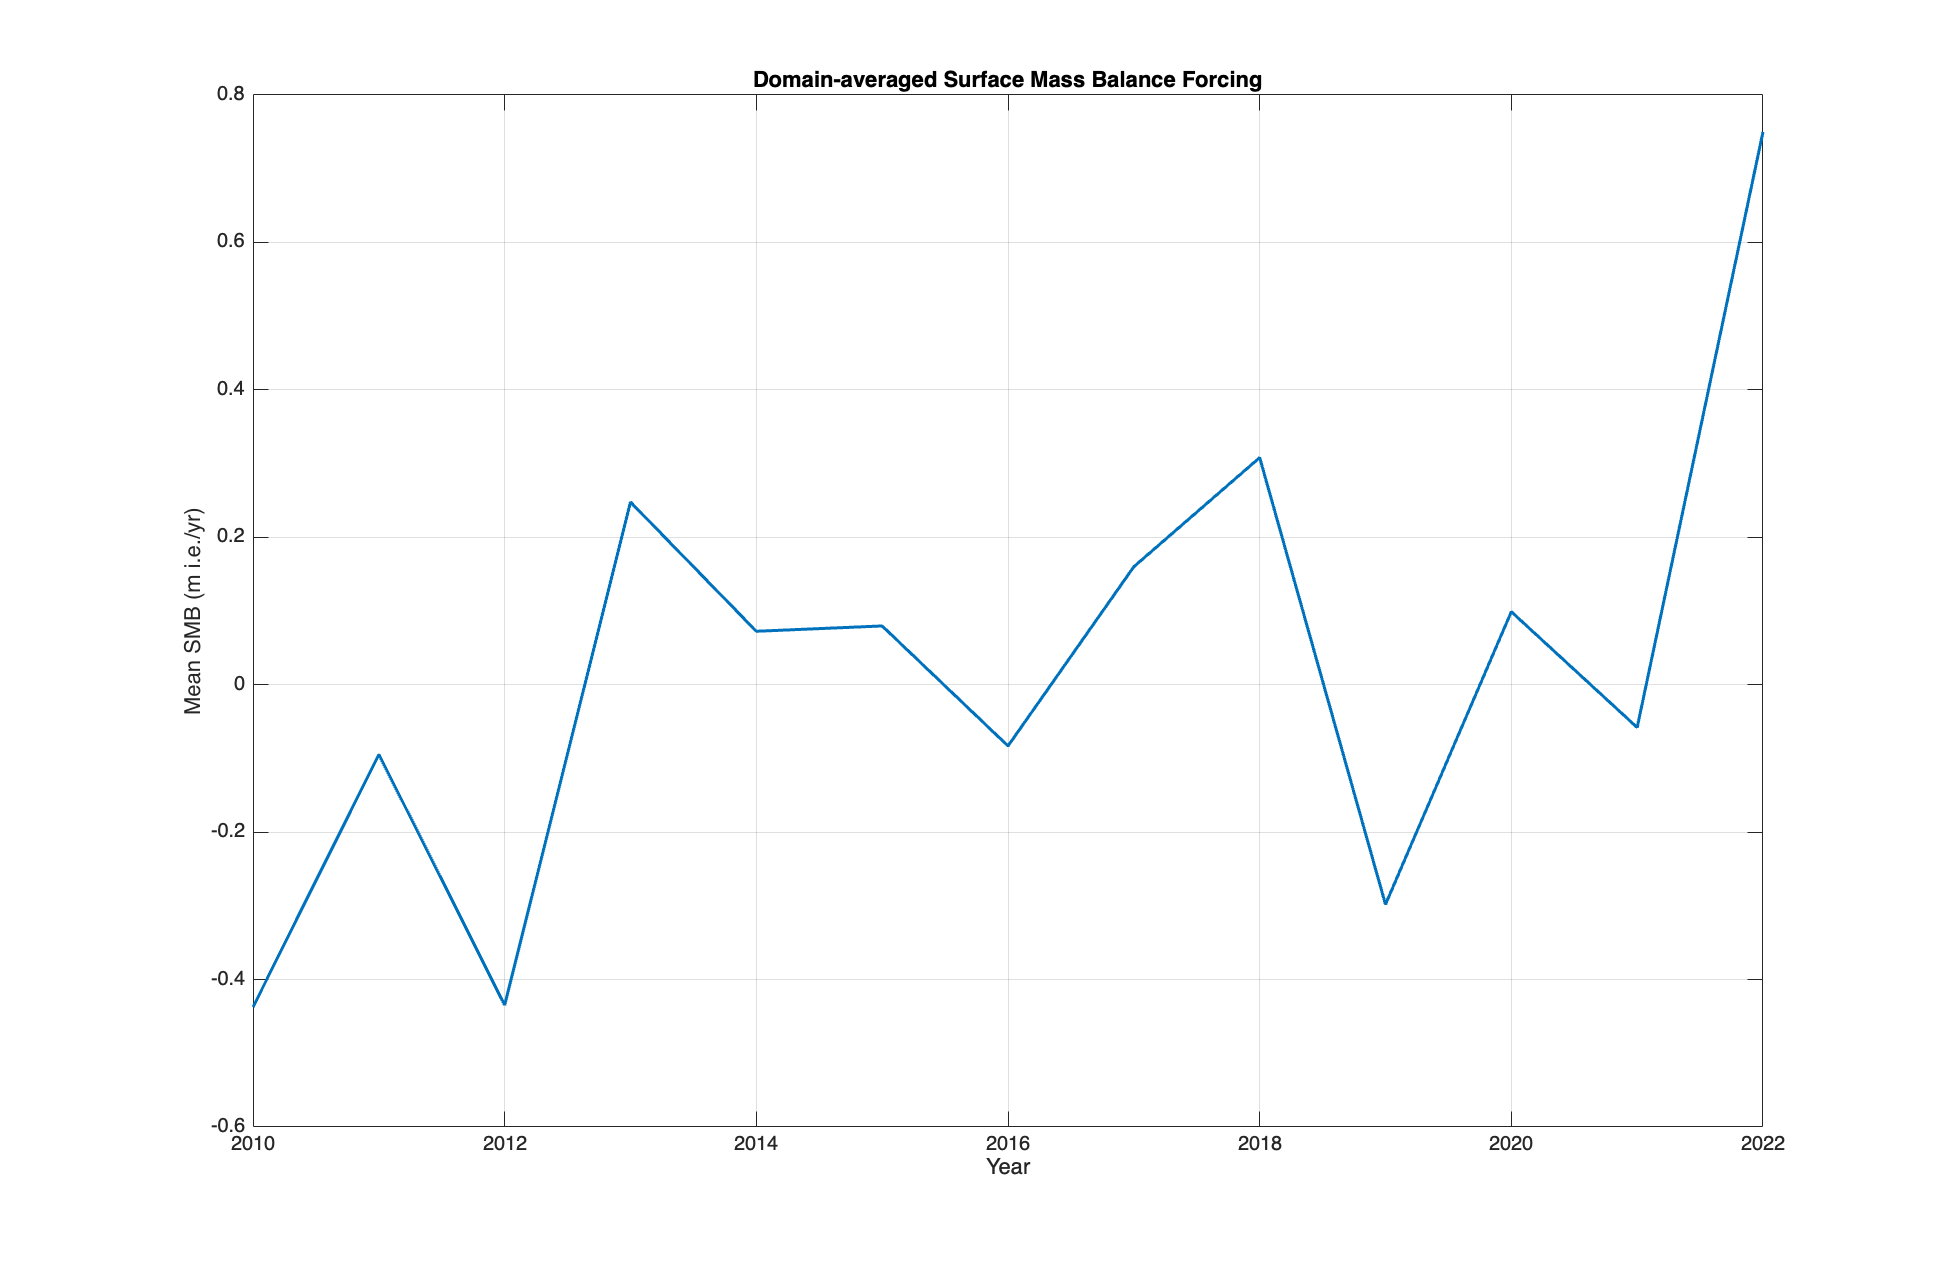

years = md.smb.mass_balance(end,:); % Extract years (stored in last row of md.smb.mass_balance)
smb_values = md.smb.mass_balance(1:end-1,:); % Extract SMB values (all vertices, without the last row)
mean_smb = mean(smb_values,1,'omitnan'); % Compute spatial mean at each year

plot(years, mean_smb, 'LineWidth',1.5);
xlabel('Year');
ylabel('Mean SMB (m i.e./yr)');
title('Domain-averaged Surface Mass Balance Forcing');
grid on;

## Running the transient simulation

%Indicate the components of transient to activate
md.transient.ismasstransport = 1;
md.transient.isstressbalance = 1;
md.transient.isgroundingline = 1;
md.transient.ismovingfront = 0;
md.transient.isthermal = 0;

%Specify time steps and length of simulation (years)
md.timestepping.start_time = 2010;
md.timestepping.time_step = 1;
md.timestepping.final_time = 2022; % 2014 to 2022 (8 years)

%Disable inverse method
md.inversion.iscontrol=0;

%Initialize fields for transient and add boundary conditions
md.initialization.vx = md.results.StressbalanceSolution.Vx;
md.initialization.vy = md.results.StressbalanceSolution.Vy;
md.initialization.vel = md.results.StressbalanceSolution.Vel;
md.masstransport.spcthickness = NaN*ones(md.mesh.numberofvertices,1);

%Request additional outputs
md.transient.requested_outputs={'IceVolume','TotalSmb','SmbMassBalance'};

%Solve transient solution and change messages provided
md.cluster = generic('name',oshostname,'np',4);
md.verbose = verbose('solution',false);
md=solve(md,'Transient');

uploading input file and queuing script
launching solution sequence on remote cluster

Ice-sheet and Sea-level System Model (ISSM) version  4.24
(website: http://issm.jpl.nasa.gov forum: https://issm.ess.uci.edu/forum/)

call computational core:
write lock file:

   FemModel initialization elapsed time:   0.310816
   Total Core solution elapsed time:       63.4957
   Linear solver elapsed time:             46.0712 (73%)

   Total elapsed time: 0 hrs 1 min 3 sec


## Planview plots

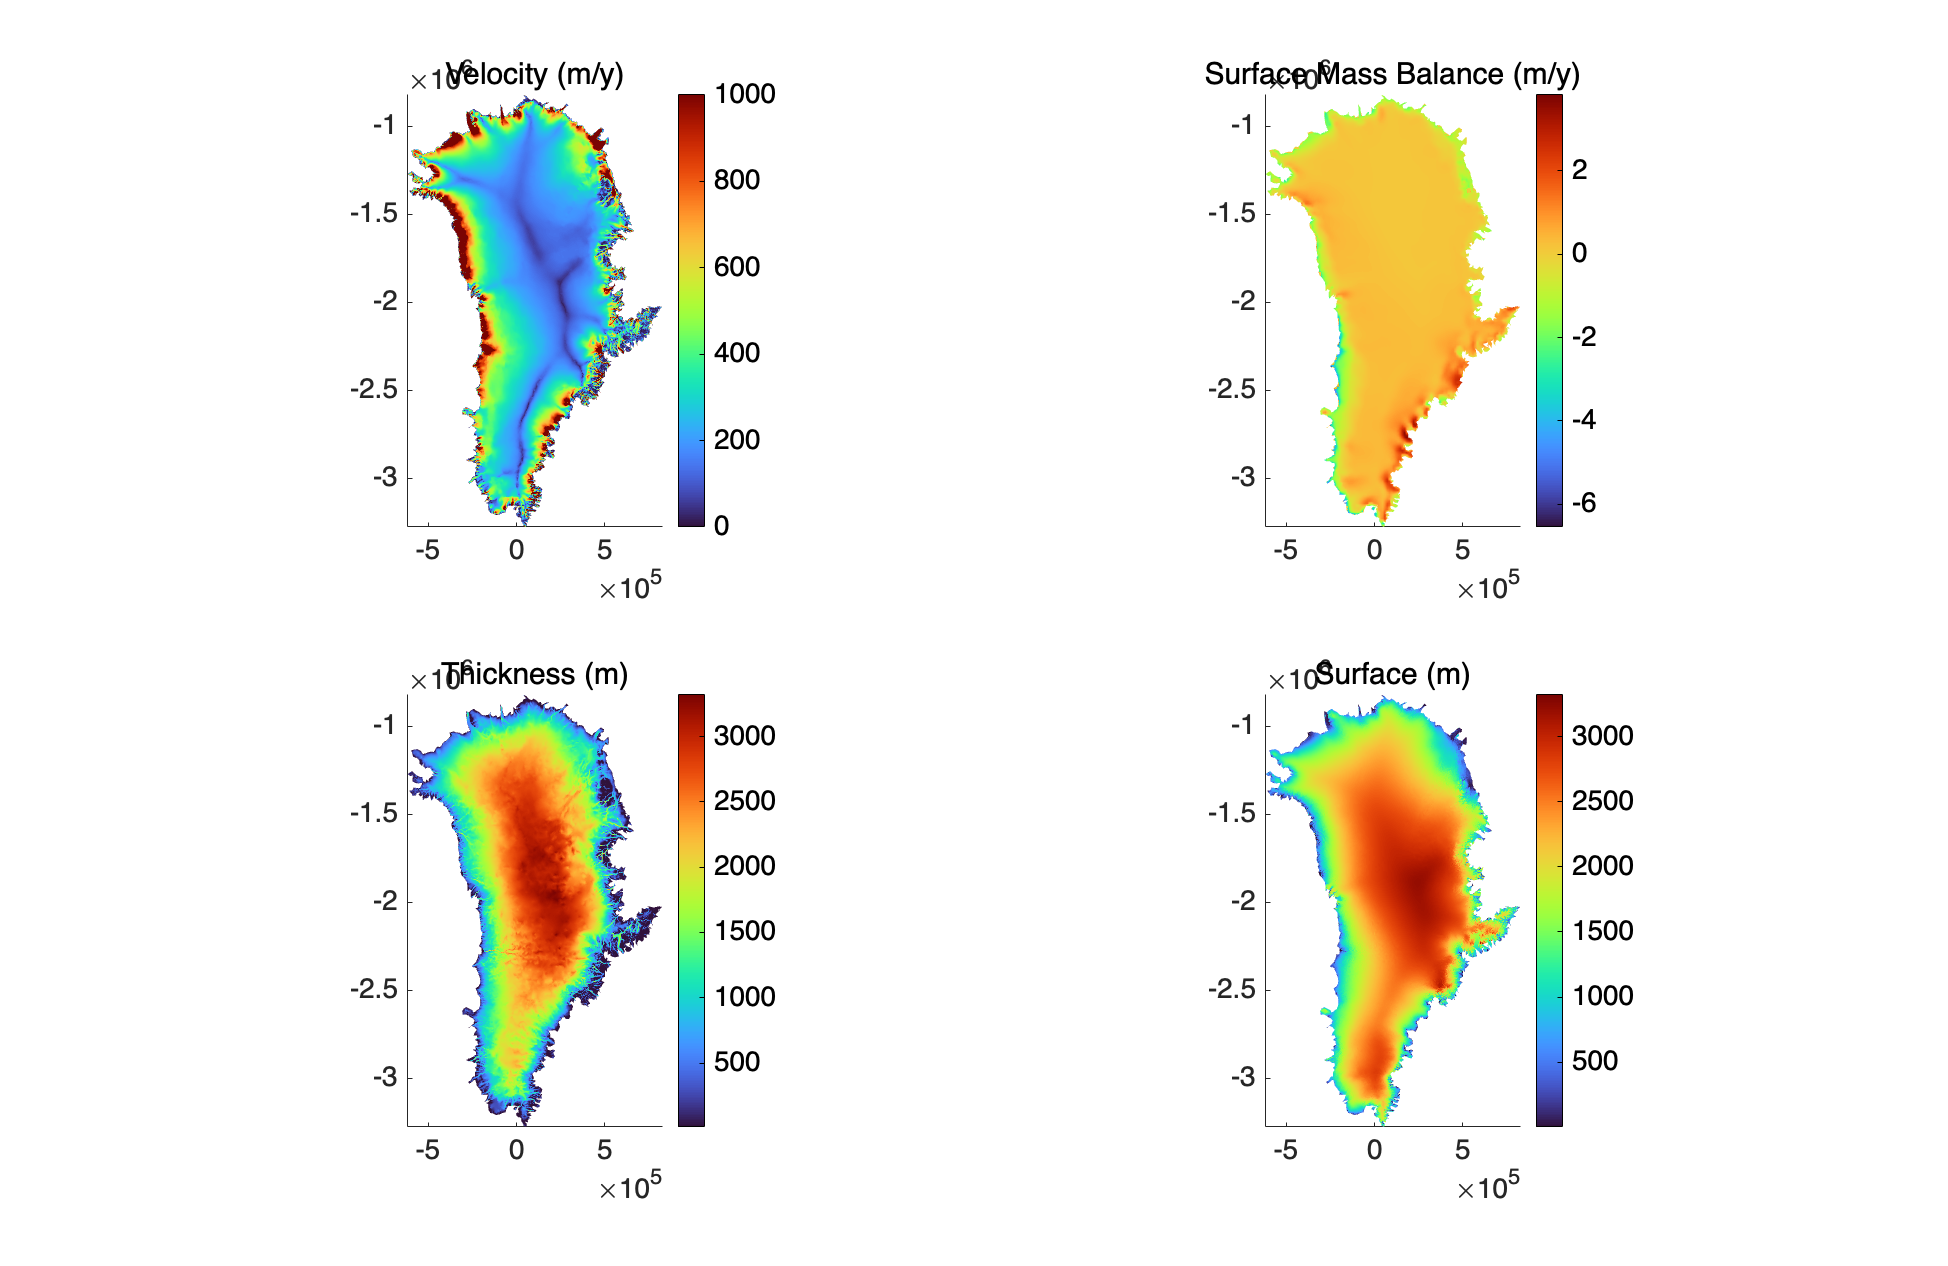

	plotmodel(md,'data',md.results.TransientSolution(end).Vel, ...
		'caxis#1', [0 1000], ...
		'title#1', 'Velocity (m/y)',...
		'data',md.results.TransientSolution(end).SmbMassBalance,...
		'title#2', 'Surface Mass Balance (m/y)',...
		'data',md.results.TransientSolution(end).Thickness,...
		'title', 'Thickness (m)',...
		'data',md.results.TransientSolution(end).Surface,...
		'title', 'Surface (m)','figposition','fullscreen');

## Line Plots

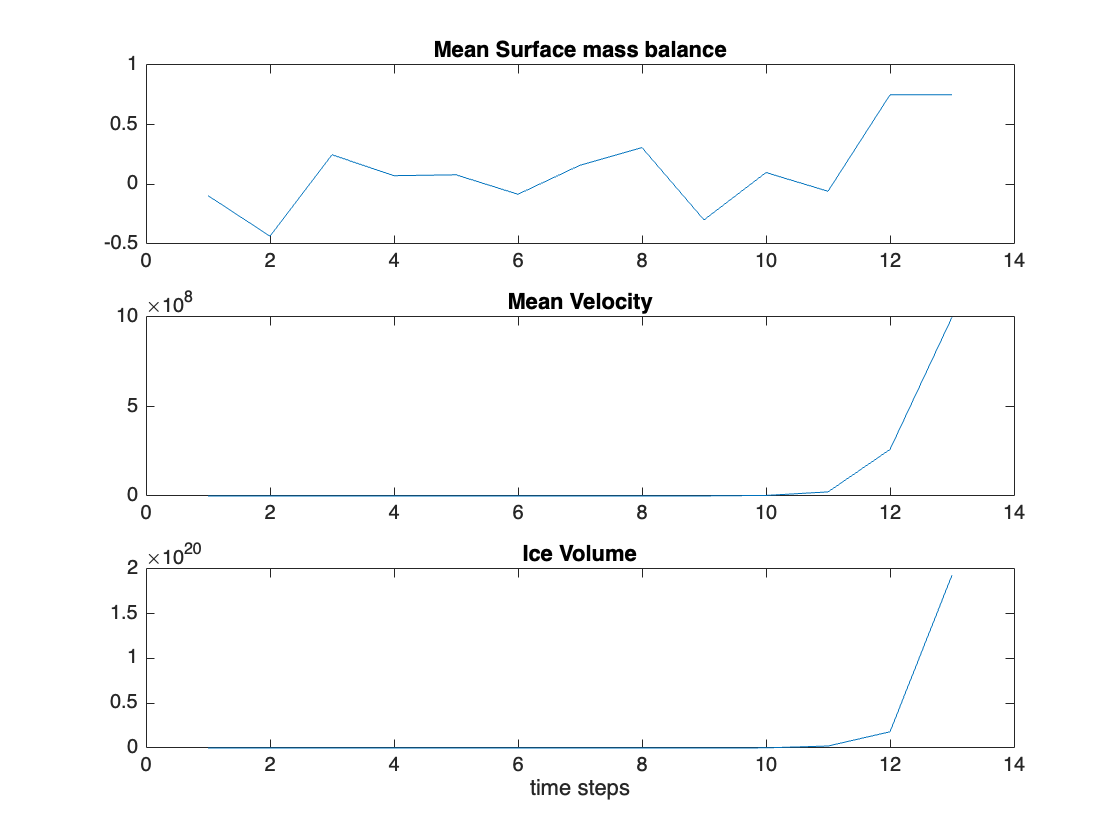

figure
lim = size(md.smb.mass_balance,2);

surfmb = []; vel = []; volume = [];
for i = 1:lim
    surfmb = [surfmb md.results.TransientSolution(i).SmbMassBalance];
    vel = [vel md.results.TransientSolution(i).Vel];
    volume = [volume md.results.TransientSolution(i).IceVolume];
end

%Plot surface mass balance
surfmb_mean = mean(surfmb,1); % mean across vertices, keep time dimension
subplot(3,1,1);
plot(1:lim, surfmb_mean);
title('Mean Surface mass balance');

%Plot velocity
vel_mean = mean(vel,1);
subplot(3,1,2);
plot(1:lim, vel_mean);
title('Mean Velocity');

%Plot Volume
subplot(3,1,3);
plot(1:lim, volume);
title('Ice Volume');
xlabel('time steps')